# Main script

Within this file, everything you need to find and evaluate your magnetic field can be found! Make sure to modify values where it's suggested, and to only run the blocks you need!

## Determine magnetic moment of dipoles

Simulate the magnetic field which arises from a collection of ideal magnetic dipoles, and determine how their magnetization should be set to achieve a target magnetic profile.

### Set general parameters

%% Here, specify where all dipoles are located. These position must me
% explicitly specified. Each row corresponds to a dipole, and its columns
% are x, y and z positions.
dipole_positions = [-2 0 0; 2 0 0; 0 -2 0; 0 2 0; 0 0 -2; 0 0 2];

% Now, for each dipole, specify its magnetic moment. Every row should
% relate to the magnetic moment of the dipole of the same row in
% 'dipole_positions'. Set values to 'nan' to indicate that the values
% should be determined by a target field.
M_x = [1 0 0; 1 0 0; 0 2 0; 0 2 0; 0 0 3; 0 0 3];
M_k = ones(size(M_x));
M_m = zeros(size(M_x));
n = length(unique(M_x))-1; % Number of free parameters

% Here, specify on which domain to evaluate the B-field. Currently, only
% discs normal to the z-axis are available
target_domain = graphene([0, 0, 0], 1, pi/4);

% Finally, specify the target magnetic field profile. Any undetermined dipole
% magnetizations will be set to approximate this field, on a 2D-domain
% defined above.
target_field_elementwise = B_field_uniform_Z(target_domain, 1);

### Set computational parameters

These parameters only affect the computational accuracy, not the problem statement

%% Ö
collision_threshold = 0.01;

### Compute stuff

Now, let the magic happen! 

%% Check if any dipole is situated exactly in the evaluation area 
dipole_in_domain = false;
% Use line below (but fix it plz) if you're really worried about this
% any(dipole_positions(:, 3) == target_domain.Z)

threshold = collision_threshold * dipole_in_domain;

% Create function from degrees-of-freedom to magnetization:
get_M = @(x) insert_params(x, M_x, M_k, M_m);

% Create function handle which returns a B-field computator B(X, Y, Z) from
% parameters x
B_func_from_x = @(x) B_function(@(xvar, X, Y, Z) get_field(X, Y, Z, dipole_positions, get_M(xvar), threshold), x);

% Create a reference field computator handle B_0(X, Y, Z)
B_0 = B_function(@(~, X, Y, Z) cell2mat(arrayfun(@(x, y, z) reshape(target_field_elementwise(x, y, z), [1 1 3]), X, Y, Z, 'UniformOutput', false)));

% Create an inner product evaluator, with information about evaluation
% domain.
inprod = inner_product(target_domain.R, target_domain.Origin, target_domain.Phi);

% GO!!!
[x, B_best] = granny_smith(B_func_from_x, B_0, inprod, n, true);

Starting to compute inner product between 1 and 1
It took 0.018166 s
Starting to compute inner product between 2 and 1
It took 0.03844 s
Starting to compute inner product between 2 and 2
It took 0.013795 s
Starting to compute inner product between 3 and 1
It took 0.040362 s
Starting to compute inner product between 3 and 2
It took 0.025801 s
Starting to compute inner product between 3 and 3
It took 0.0088788 s


### Plotting the result

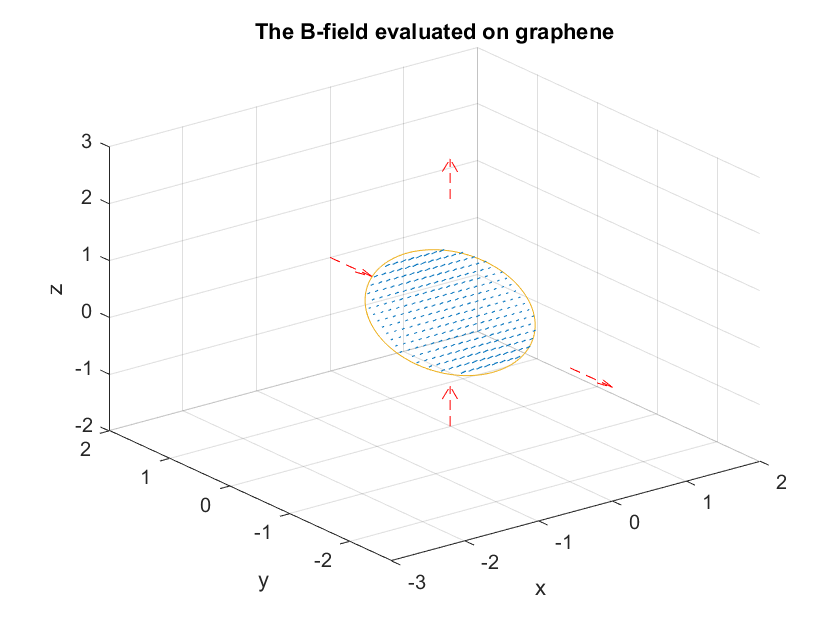

%% Select the amount of discretization points along the diameter
N = 20;

% Create the mesh
% Create the mesh
[X,Y,Z] = meshgrid(linspace(-target_domain.R,target_domain.R,N),...
    linspace(--target_domain.R,-target_domain.R,N),0);

i = X.^2 + Y.^2 <= target_domain.R^2;

[X, Y, Z] = target_domain.Transform(X, Y, Z);


% Assigns the B-field and shows the quiver plot
B = B_best(X,Y,Z);

Bx = squeeze(B(:,:,1));
By = squeeze(B(:,:,2));
Bz = squeeze(B(:,:,3));

m = get_M(x);

b_plot(X(i), Y(i), Z(i) ,Bx(i), By(i), Bz(i), dipole_positions, m, target_domain)


b_field_at_origo = reshape(B_best(target_domain.Origin(1),target_domain.Origin(2),target_domain.Origin(3)), [1,3]);
b_field_at_edge = reshape(B_best(target_domain.Origin(1)+target_domain.R,target_domain.Origin(2),target_domain.Origin(3)), [1,3]);
b_str_at_origo = dot(target_domain.Normal, b_field_at_origo);
b_str_at_edge = dot(target_domain.Normal, b_field_at_edge);
b_uniformity = b_str_at_edge/b_str_at_origo